ZDT1 test function of Zitzler, Deb and Thiele, 2000

This is a box-constrained continuous $d$-dimensional ($d>1$) multi-objective problem.

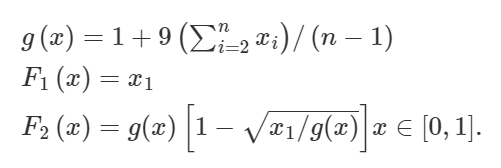

function Fx = AMALGAM_ZDT1(x,d)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%AMALGAM_ZDT1: ZDT1 bivariate test function of Zitzler et al. 2000        %
%                                                                         %
%  SYNOPSIS                                                               %
%   Fx = AMALGAM_ZDT1(x,d)                                                %
%  where                                                                  %
%   x       [input] 1xd parameter vector                                  %
%   d       [input] # parameters                                          %
%   Fx      [outpt] pair of objective function values                     %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
% ZDT1 example from the following paper                                   %
%  Zitzler, E., K. Deb, and L. Thiele (2000), Comparison of               %
%      Multiobjective Evolutionary Algorithms: Empirical Results,         %
%      Evolutionary Computation, 8 (2), 183-195                           %
%      https://sop.tik.ee.ethz.ch/publicationListFiles/zdt2000a.pdf       %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
%  © Written by Jasper A. Vrugt, Jan. 2005                                %
%  Los Alamos National Laboratory                                         %
%  University of California Irvine                                        %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %

f = x(1);                                   % f(x)
g = 1 + 9/(d-1)*sum(x(2:d));                % g(x)
h = 1 - sqrt(f./g);                         % h(x)
Fx(1) = f; Fx(2) = g.*h;                    % Pair of FX values

end